# Shift and Add Image Restoration Procedure

### A. Locate image files

foldername = "16_08_5";
valid_files = dir(foldername + "/*." + "tif");
tracking_method = 'circle';

num_images = length(valid_files);

The final line counts the number of images to be imported.

### B. Construct array of resized image data

images = [];
scale_fact = 1;

for i = 1:num_images
     images(:,:,:,i) = imresize(imread(foldername+"/"+valid_files(i).name),scale_fact,'bicubic');
end

A reference image is used for the `crosscorr` method and also to determine the number of channels

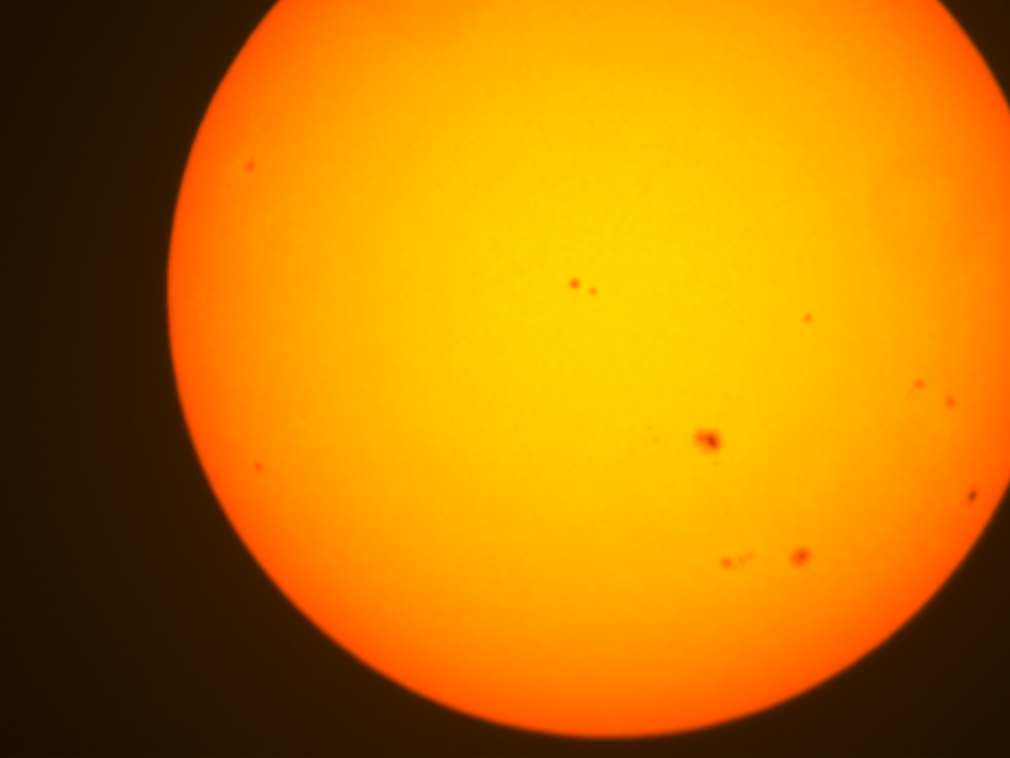

ans =   Image with properties:

                Data: [960×1280×3 uint8]
       Interpolation: "auto"
        DisplayRange: [0 255]
    DisplayRangeMode: "type-range"

           AlphaData: 1
              Parent: [1×1 Viewer]
             Visible: on


reference = images(:,:,:,5);
imageshow(uint8(reference))

num_channels = size(reference, 3);

### C. Apply relevant tracking method

peaks = [];
centres = [] ;

for i = 1:num_images
    current_image = images(:,:,:,i);
    current_image_channel = sum(current_image(:,:,:),3);
    [im_height, im_length] = size(current_image_channel);
    imshow(uint8(current_image))
    hold on
    xlim([0,im_length])
    ylim([0,im_height])
    
    switch tracking_method
        case 'peaks'            

The brightest point in each image is found by taking the sum across all channels, and then finding the maximum (in the case of multiple maxima, identifies their midpoint)

            maximum = max(current_image_channel, [], 'all');
            [maxrow, maxcol] = find(current_image_channel == maximum);
            maxrow = round(mean(maxrow));
            maxcol = round(mean(maxcol));
            peaks(i,:) = [maxrow, maxcol];

Each image is shown and its peak plotted to produce an animation.

            plot(peaks(:,2), peaks(:,1), 'r-', 'LineWidth',1)
            plot(maxcol, maxrow, 'or', 'MarkerSize', 15, 'MarkerFaceColor', 'none')

For pictures with multiple bright points, you might want to smooth the line plotted, assuming a well-ordered set of photos with an individual bright feature that stays moving in the same direction.

            smoothing = true;
            if smoothing
                for dim = 1:2
                    peaks(:,dim) = round(smoothdata(peaks(:,dim),'sgolay',50));
                end
            end

        case 'circle'            
            radius_range = [0.2*im_height 2*im_height];

Please note the radius range to detect the sun in the example is around 600 pixels.

This method identifies circular objects (bright circles) in the image data, and therefore finds the centre as it moves through the frame.

            [centres(i,:),radius] = imfindcircles(uint8(current_image),radius_range,ObjectPolarity='bright',Sensitivity=0.95);
            viscircles(centres(i,:),radius,'Color','b','LineWidth',1);
            plot(centres(:,1), centres(:,2), 'b-','LineWidth',1)
            plot(centres(i,1), centres(i,2), 'ob', 'MarkerSize', 15, 'MarkerFaceColor', 'b')

As MATLAB interpolates the centre of the circular object, a rounding function must be used to later expand the image according to the Shift and Add method.

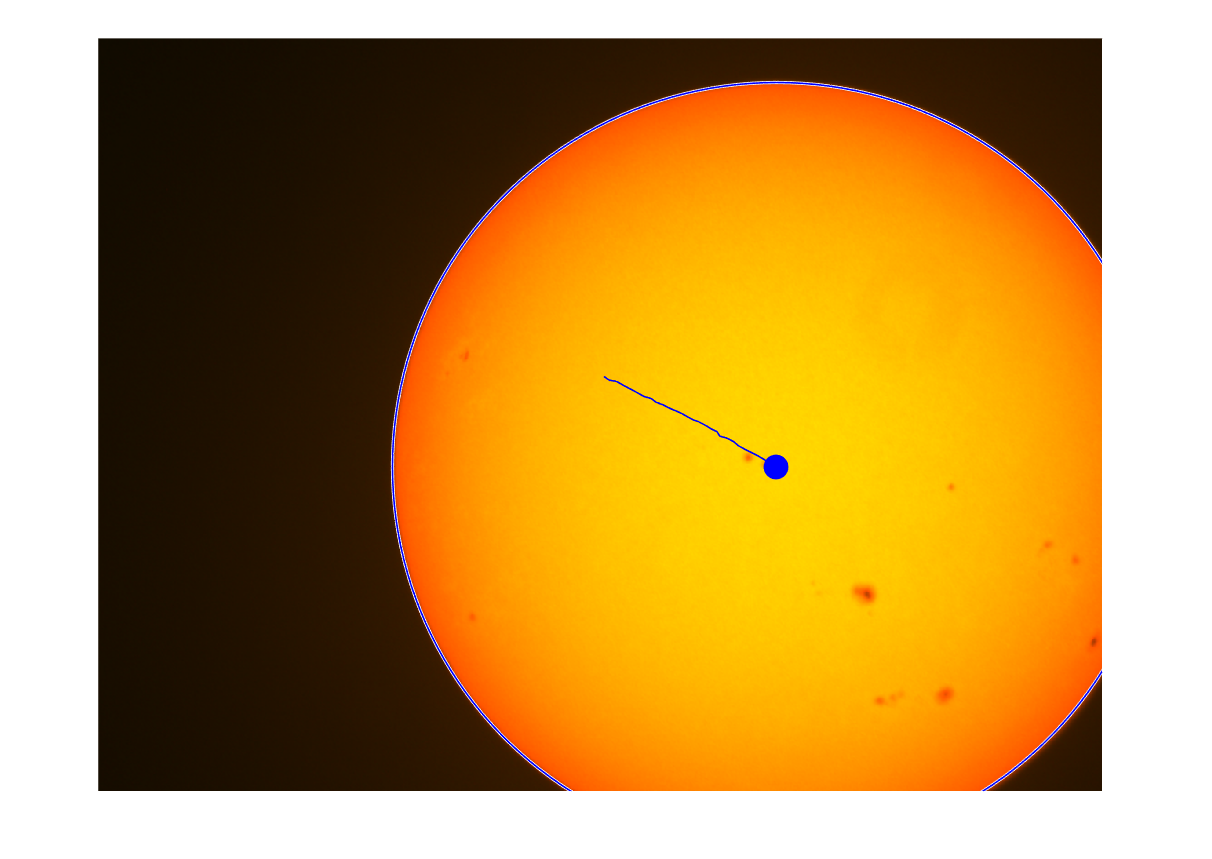

            peaks(i,:) = [clip(round(centres(i,2)),0,im_height), clip(round(centres(i,1)),0,im_length)] ;
        case 'crosscorr'
            % nope !
    end
    drawnow
    hold off
end

### D. Calculate image expansion as the range of peaks

y_enlargement = max(peaks(:,1)) - min(peaks(:,1));
x_enlargement = max(peaks(:,2)) - min(peaks(:,2));

The image will be expanded by the range of each co-ordinate across the peaks.

The difference between the rightmost / lowermost peak and the others is calculated as a shift which will be used to display the composite image.

x_shifts = max(peaks(:,1)) - peaks(:,1);
y_shifts = max(peaks(:,2)) - peaks(:,2);
shifts = [x_shifts , y_shifts];

### E. Shift and Add!

The Shift and Add canvas is set by expanding the original image size to be able to overlay each image and displaying each one fully.

num_frames = 10;
frame_repetition = 1 ;

for k = round(linspace(1,num_images,num_frames))
    shift_and_added = 255*ones(im_height + y_enlargement, im_length + x_enlargement, num_channels);
    weights = zeros(im_height + y_enlargement, im_length + x_enlargement);

The `weights` array described the number of images layered on each individual pixel of the final result.

This shift slice defines a a series of x co-ordinates and co-ordinates, in other words the region in which each image will be drawn. Note that an additional `1` is added due to MATLAB's 1-based indexing *e.g. where the x-shift is *`0`*, this should be drawn from the first column of pixels*.

    shift_slices = cell(k, 1);
    for i = 1:k
        current_shift = shifts(i, :);
        shift_slices{i} = {...
            current_shift(1) + 1:im_height + current_shift(1), ...
            current_shift(2) + 1:im_length + current_shift(2)};
    end
    

The top of the loop defines the shift slice, and the bottom resets the relevant pixels on the canvas that each image will be drawn back to black `[0,0,0]`

    for channel = 1:num_channels
        for i = 1:k
            current_shift_slice = shift_slices{i};
            shift_and_added(current_shift_slice{1}, current_shift_slice{2}, channel) = 0;
        end
    end
    

The final loop overlays the images.

    for i = 1:k
        current_image = images(:,:,:,i);
        current_shift_slice = shift_slices{i};
        weights(current_shift_slice{1}, current_shift_slice{2}) = ...
            weights(current_shift_slice{1}, current_shift_slice{2}) + 1;
        for channel = 1:num_channels
            shift_and_added(current_shift_slice{1}, current_shift_slice{2}, channel) = ...
                shift_and_added(current_shift_slice{1}, current_shift_slice{2}, channel) + current_image(:,:,channel);
        end
    end

The weight for each pixel is increased by 1 if it is included in the `current_shift_slice`. These are then averaged over the weights, avoiding division by zero for any pixels not included, and normalising the final processed image.

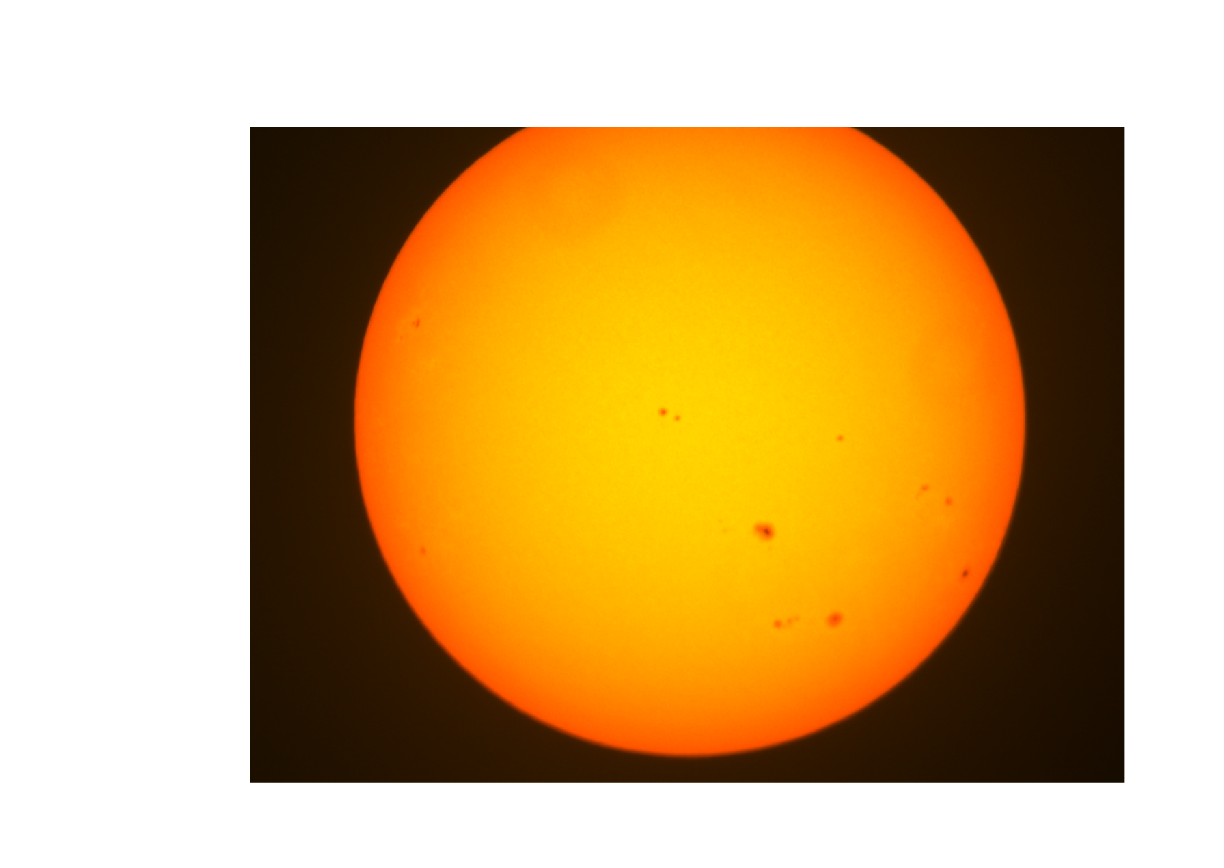

    shift_and_added = uint8(shift_and_added ./ max(weights, 1));
    
    if min(shift_and_added, [], 'all') <= 0
        shift_and_added = shift_and_added - min(shift_and_added, [], 'all');
    end
    
    shift_and_added = uint8(shift_and_added * (255 / max(shift_and_added, [], 'all')));
    
    imshow(shift_and_added)

    if k == 1
        gif('shift_and_add.gif')
    else
        gif
    end

    for f = 1:frame_repetition-1
        gif
    end
end

imageshow(shift_and_added)
exportgraphics(gcf,'shift_and_add.png')